clear; close; clc;
%flight condtino for cruise
load('CARTRIDGE_105_MILLIMETER_HERA_M927.mat')

d = CARTRIDGE_105_MILLIMETER_HERA_M927.Hydrolic_Diameter;
l = CARTRIDGE_105_MILLIMETER_HERA_M927.Projectile_Length;
       

S_ref = pi*d/4;
Weight_50 = (CARTRIDGE_105_MILLIMETER_HERA_M927.Projectile_Mass - CARTRIDGE_105_MILLIMETER_HERA_M927.Propellant_Mass/2) * 9.81; % wieght at 50% fuel load
Lift = Weight_50;

isCoasting = true; % we are doing both true and false (this should not be defined here)

height = 1000; % we will do this for various altitudes. not yet implemented

%for various velocities (varying q_bar)
Vmin = 100; Vmax = 680; %m/s
Vstep = 1; %m/s

V_list = Vmin:Vstep:Vmax % velocity range

V_list =    100   101   102   103   104   105   106   107   108   109   110   111   112   113   114   115   116   117   118   119   120   121   122   123   124   125   126   127   128   129   130   131   132   133   134   135   136   137   138   139   140   141   142   143   144   145   146   147   148   149


Vsteps = length(V_list);

% initialize looop solution arrays
alpha_optimum = zeros(Vsteps,0);
q_bars = zeros(Vsteps,0);
L_over_D_1g = zeros(Vsteps,0);
L_over_D_1g_powered = zeros(Vsteps,0);

for j = 1:Vsteps
    V = V_list(j);
    [~,a,~,rho] = atmosisa(height);
    M = V/a;
    
    q = 1/2*rho*V^2;
    C_L = Lift/(S_ref*q);
    
    %newton raphson to converge on the optimal value for alpha for lift=weight
    alpha_guess = .001;
    for i = 1:10000
        C_N = normalForceCoeff_liftingBody(l,d/2,d/2,0,alpha_guess);
        C_N_alpha = normalForce_withRespectTo_alpha(d/2,d/2,0);
        alpha_guess = alpha_guess - (C_N-C_L)/C_N_alpha;
    end
    
    alpha_optimum(j) = alpha_guess;
    L_over_D_1g(j) = lift_to_drag_ratio_body(normalForceCoeff_liftingBody(l,d/2,d/2,0,alpha_optimum(j)),dragCoeff_zeroLift_body(M,q,CARTRIDGE_105_MILLIMETER_HERA_M927.Projectile_Length,CARTRIDGE_105_MILLIMETER_HERA_M927.Nose_Length,d,CARTRIDGE_105_MILLIMETER_HERA_M927.Nose_Tip_Diameter,CARTRIDGE_105_MILLIMETER_HERA_M927.Boattail_Diameter,CARTRIDGE_105_MILLIMETER_HERA_M927.Nozzle_Exit_Area,isCoasting),alpha_optimum(j));
    % only impact of thrust is here (there seems to be no impact on L/D)
    L_over_D_1g_powered(j) = lift_to_drag_ratio_body(normalForceCoeff_liftingBody(l,d/2,d/2,0,alpha_optimum(j)),dragCoeff_zeroLift_body(M,q,CARTRIDGE_105_MILLIMETER_HERA_M927.Projectile_Length,CARTRIDGE_105_MILLIMETER_HERA_M927.Nose_Length,d,CARTRIDGE_105_MILLIMETER_HERA_M927.Nose_Tip_Diameter,CARTRIDGE_105_MILLIMETER_HERA_M927.Boattail_Diameter,CARTRIDGE_105_MILLIMETER_HERA_M927.Nozzle_Exit_Area,false),alpha_optimum(j));
    q_bars(j) = q;
end

%cruise_results = {alpha_optimum, L_over_D_1g, L_over_D_1g_powered, q_bars} % as cell array
cruise_result.alpha_optimum = alpha_optimum;
cruise_result.alpha_optimum = q_bars;
cruise_result.L_over_D_1g = L_over_D_1g;
cruise_result.L_over_D_1g_powered = L_over_D_1g_powered;
cruise_result.alt = height;
%cruise_results = {cruise_result} % something like this to madd my results
%to the cell array

alpha_optimum

alpha_optimum =     0.1004    0.0987    0.0972    0.0956    0.0941    0.0927    0.0913    0.0899    0.0885    0.0872    0.0859    0.0846    0.0833    0.0821    0.0809    0.0798    0.0786    0.0775    0.0764    0.0753    0.0743    0.0733    0.0723    0.0713    0.0703    0.0694    0.0684    0.0675    0.0666    0.0657    0.0649    0.0641    0.0632    0.0624    0.0616    0.0608    0.0601    0.0593    0.0586    0.0579    0.0572    0.0565    0.0558    0.0551    0.0544    0.0538    0.0532    0.0525    0.0519    0.0513


L_over_D_1g

L_over_D_1g =     1.7011    1.6775    1.6540    1.6309    1.6079    1.5852    1.5628    1.5406    1.5187    1.4971    1.4757    1.4546    1.4338    1.4133    1.3931    1.3731    1.3534    1.3340    1.3149    1.2961    1.2776    1.2593    1.2413    1.2236    1.2062    1.1891    1.1722    1.1556    1.1392    1.1231    1.1073    1.0917    1.0764    1.0613    1.0465    1.0319    1.0176    1.0035    0.9896    0.9759    0.9625    0.9493    0.9363    0.9235    0.9109    0.8986    0.8864    0.8744    0.8627    0.8511


L_over_D_1g_powered

L_over_D_1g_powered =     1.7015    1.6779    1.6545    1.6313    1.6084    1.5857    1.5632    1.5411    1.5192    1.4975    1.4761    1.4550    1.4342    1.4137    1.3935    1.3735    1.3538    1.3344    1.3153    1.2965    1.2780    1.2597    1.2417    1.2240    1.2066    1.1894    1.1726    1.1559    1.1396    1.1235    1.1077    1.0921    1.0768    1.0617    1.0468    1.0323    1.0179    1.0038    0.9899    0.9762    0.9628    0.9496    0.9366    0.9238    0.9112    0.8989    0.8867    0.8747    0.8629    0.8514


q_bars

q_bars = 1.0e+05 *

    0.0556    0.0567    0.0578    0.0590    0.0601    0.0613    0.0625    0.0636    0.0648    0.0660    0.0673    0.0685    0.0697    0.0710    0.0722    0.0735    0.0748    0.0761    0.0774    0.0787    0.0800    0.0814    0.0827    0.0841    0.0855    0.0868    0.0882    0.0896    0.0911    0.0925    0.0939    0.0954    0.0968    0.0983    0.0998    0.1013    0.1028    0.1043    0.1059    0.1074    0.1089    0.1105    0.1121    0.1137    0.1153    0.1169    0.1185    0.1201    0.1217    0.1234


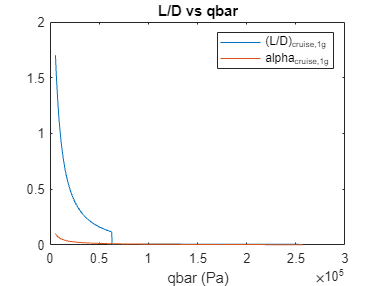


% plot trend of l/d and alpha
plot(q_bars,[L_over_D_1g; alpha_optimum]); title("L/D vs qbar"); xlabel("qbar (Pa)"); legend(["(L/D)_{cruise,1g}", "alpha_{cruise,1g}"]);

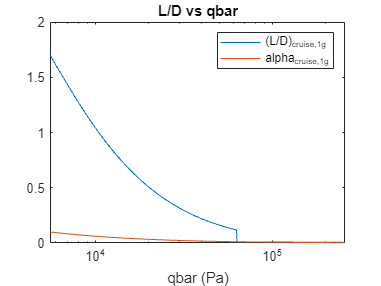

semilogx(q_bars,[L_over_D_1g; alpha_optimum]); title("L/D vs qbar"); xlabel("qbar (Pa)"); legend(["(L/D)_{cruise,1g}", "alpha_{cruise,1g}"]);

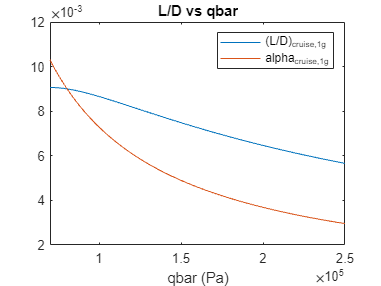


%region of intrest
plot(q_bars,[L_over_D_1g; alpha_optimum]); title("L/D vs qbar"); xlabel("qbar (Pa)"); legend(["(L/D)_{cruise,1g}", "alpha_{cruise,1g}"]); xlim([.7e5, 2.5e5]);

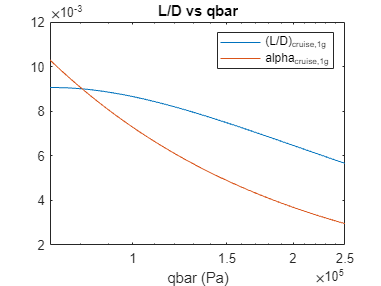

%log plot to match fleeman
semilogx(q_bars,[L_over_D_1g; alpha_optimum]); title("L/D vs qbar"); xlabel("qbar (Pa)"); legend(["(L/D)_{cruise,1g}", "alpha_{cruise,1g}"]); xlim([.7e5, 2.5e5]);

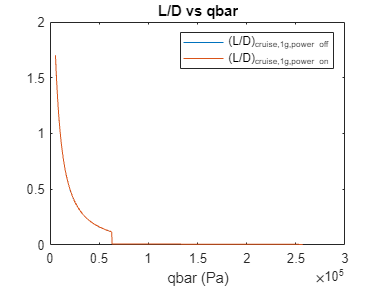



%compare powered and unpowerd
plot(q_bars,[L_over_D_1g; L_over_D_1g_powered]); title("L/D vs qbar"); xlabel("qbar (Pa)"); legend(["(L/D)_{cruise,1g,power off}", "(L/D)_{cruise,1g,power on}"]); % this plot is unintresting as drag reduction is negligeable